
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   PART 1


%part1_1

rng(1)
N=2000;
normal_vector=random('norm',0,sqrt(1),1,N)

normal_vector =    -0.6490    1.1812   -0.7585   -1.1096   -0.8456   -0.5727   -0.5587    0.1784   -0.1969    0.5864   -0.8519    0.8003   -1.5094    0.8759   -0.2428    0.1668   -1.9654   -1.2701    1.1752    2.0292   -0.2752    0.6037    1.7813    1.7737   -1.8651   -1.0511   -0.4174    1.4022   -1.3677   -0.2925    1.2708    0.0660    0.4513   -0.3222    0.7884    0.9287   -0.4908    1.7972    0.5907   -0.6358    0.6033   -0.5352   -0.1551    0.6121   -1.0443   -0.3456   -1.1714   -0.6856    0.9262   -1.4817


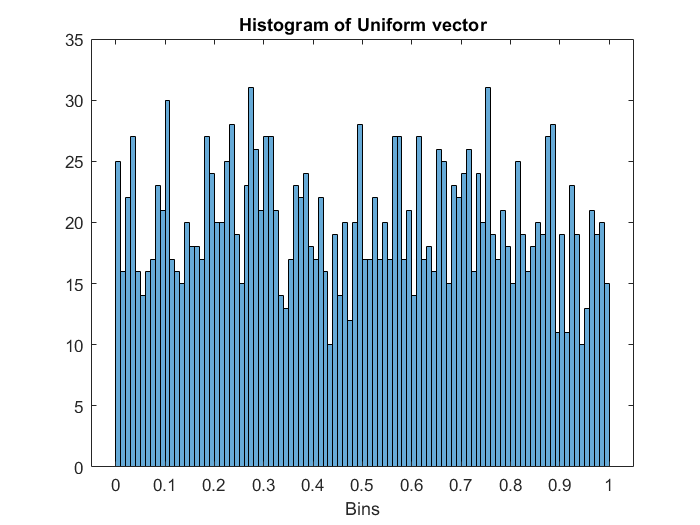

a=0;
b=1;
r = a + (b-a)*rand(N,1);
uniform_vector=r.';
figure(1)
histogram(uniform_vector,100)
title('Histogram of Uniform vector');
xlabel('Bins');

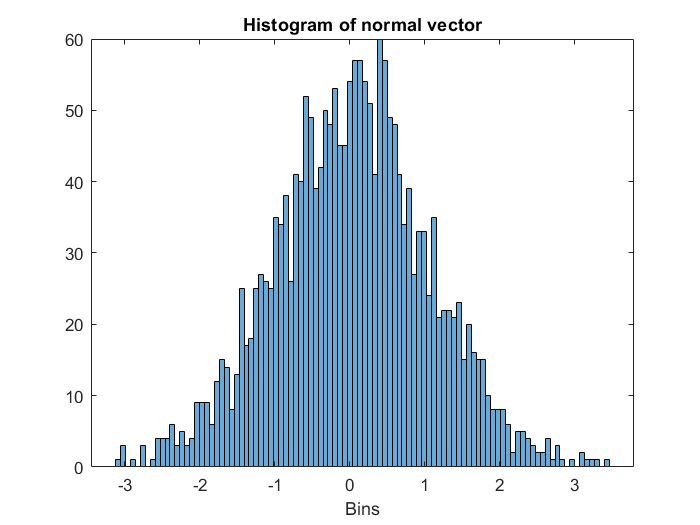

figure(2)
histogram(normal_vector,100)
title('Histogram of normal vector');
xlabel('Bins');

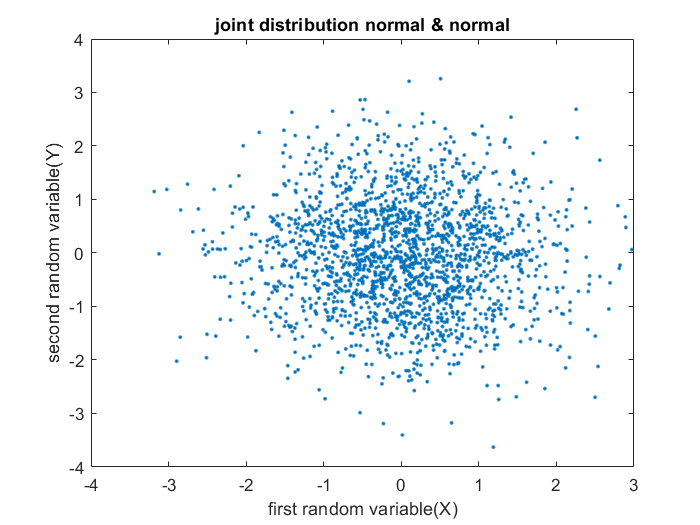


%part1_2

normal_vector1=random('norm',0,sqrt(1),1,N);
normal_vector2=random('norm',0,sqrt(1),1,N);
a=-sqrt(3);
b=+sqrt(3);
R1_uniform = a + (b-a)*rand(N,1);
R2_uniform = a + (b-a)*rand(N,1);

%Guassian & Guassian joint distribution
x = normal_vector1;
y = normal_vector2;
figure(3)
plot(x,y,".")
title('joint distribution normal & normal');
xlabel('first random variable(X)');
ylabel('second random variable(Y)')

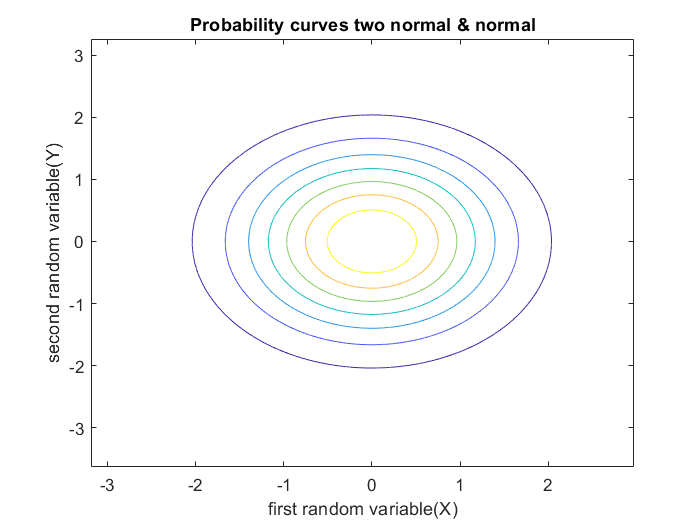

figure(4)
monhani_hamehtemal_func(x,y)               %%Probability curves
title('Probability curves two normal & normal');
xlabel('first random variable(X)');
ylabel('second random variable(Y)')

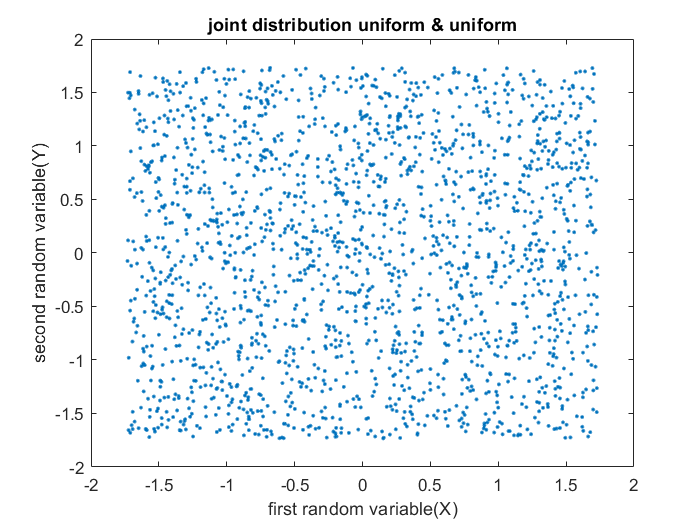

%uniform & uniform joint distribution
x = R1_uniform;
y = R2_uniform;
figure(5)
plot(x,y,".")
title('joint distribution uniform & uniform');
xlabel('first random variable(X)');
ylabel('second random variable(Y)')

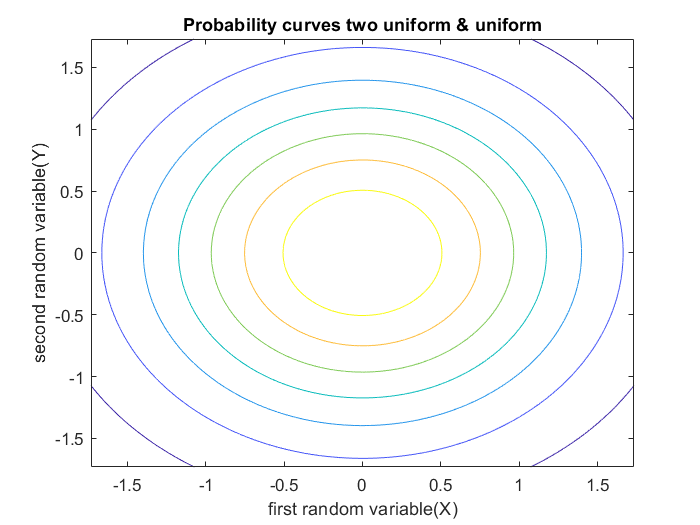

figure(6)
monhani_hamehtemal_func(x,y)               %%Probability curves
title('Probability curves two uniform & uniform');
xlabel('first random variable(X)');
ylabel('second random variable(Y)')

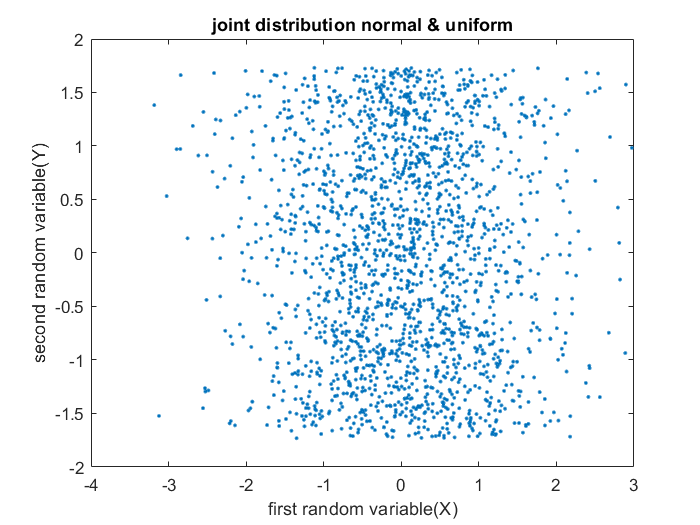

%Guassian & uniform joint distribution
x =normal_vector1;
y =R1_uniform;
figure(7)
plot(x,y,".")
title('joint distribution normal & uniform');
xlabel('first random variable(X)');
ylabel('second random variable(Y)');

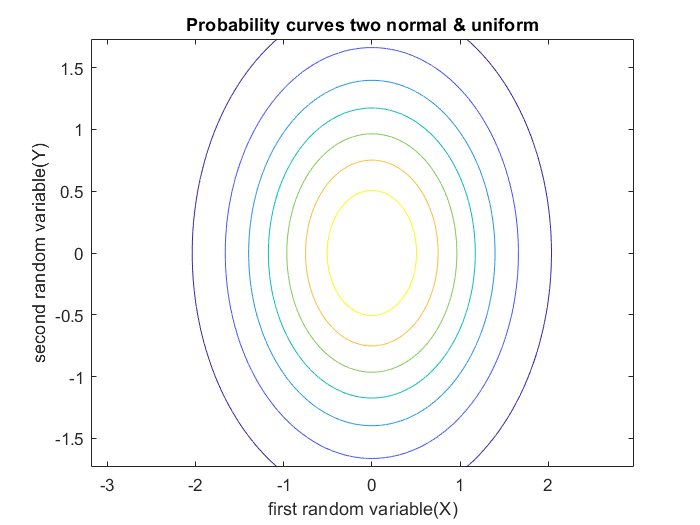

figure(8)
monhani_hamehtemal_func(x,y)               %%Probability curves
title('Probability curves two normal & uniform');
xlabel('first random variable(X)');
ylabel('second random variable(Y)')

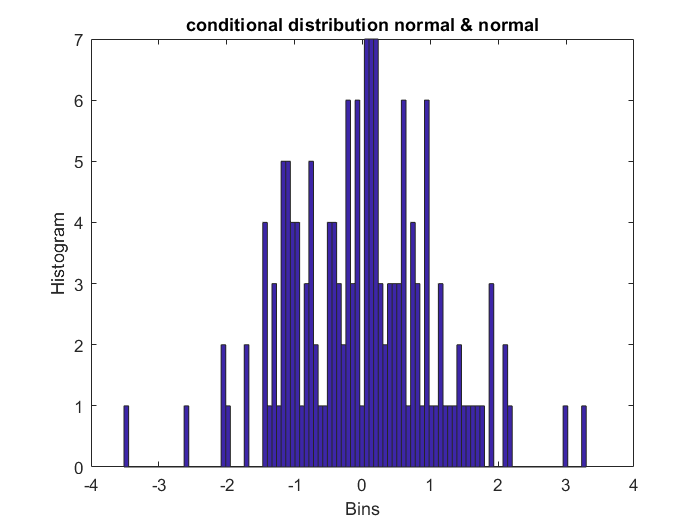


%part1_3

%Guassian & Guassian conditional distribution

X=random('norm',0,sqrt(1),1,N);  %first random variable(X)
Y=random('norm',0,sqrt(1),1,N);  %second random variable(X)

count=0;
for i=1:1:2000
    
if(0.4<Y(i) && Y(i)<0.6)
count=count+1;
conditional_vectorA(count)=X(i);   
end
end
figure(9)
hist(conditional_vectorA,100)
title('conditional distribution normal & normal');
xlabel('Bins');
ylabel('Histogram');

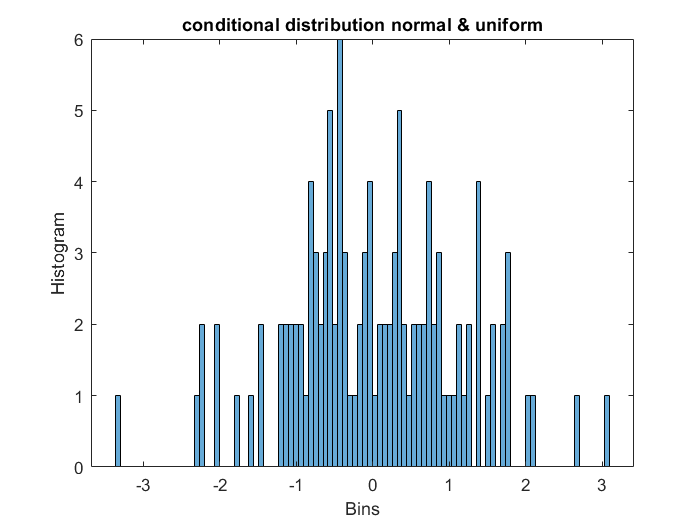


%Guassian & uniform conditional distribution
a=-sqrt(3);
b=+sqrt(3);
Y= a + (b-a)*rand(N,1);   %second random variable(Y)

count=0;
for i=1:1:2000
if(0.4<Y(i) && Y(i)<0.6)
count=count+1;
conditional_vectorB(count)=X(i);   
end
end
figure(10)
histogram(conditional_vectorB,100)
title('conditional distribution normal & uniform');
xlabel('Bins');
ylabel('Histogram');

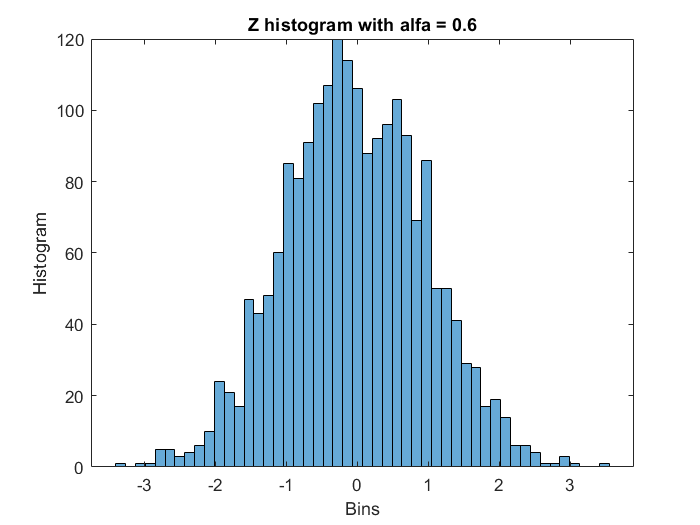



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   PART 2

%part2_1

X= normal_vector1;
Y= normal_vector2;
Alfa0=0.6;
Z0=Alfa0*X+sqrt(1-Alfa0^2)*Y;
figure(11)
histogram(Z0,50)       % we expect that the histogram would be the same with N(0,1) 
title('Z histogram with alfa = 0.6');
xlabel('Bins');
ylabel('Histogram');

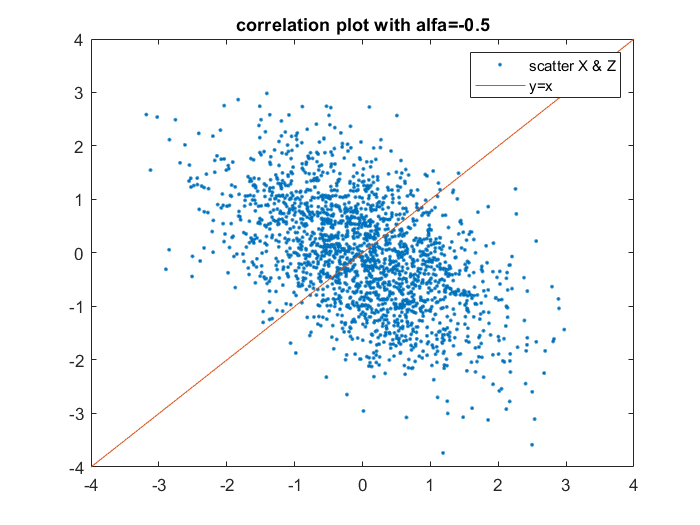


% Analysis with alfa=-0.5
Alfa1=-0.5;
Z1=Alfa1*X+sqrt(1-Alfa1^2)*Y;            
figure(12)
x=-4:0.01:4;
y=-4:0.01:4;
plot(X,Z1,".",x,y)
title('correlation plot with alfa=-0.5')
legend('scatter X & Z','y=x')

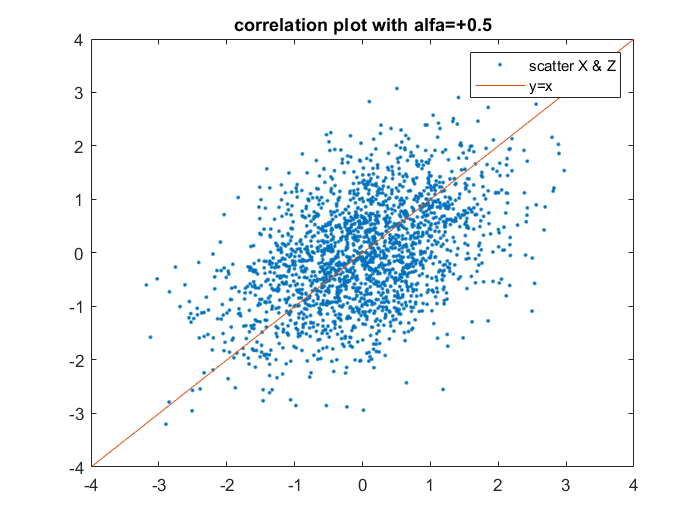

% Analysis with alfa=+0.5
Alfa2=+0.5;
Z2=Alfa2*X+sqrt(1-Alfa2^2)*Y;            
figure(13)
x=-4:0.01:4;
y=-4:0.01:4;
plot(X,Z2,".",x,y)
title('correlation plot with alfa=+0.5')
legend('scatter X & Z','y=x')

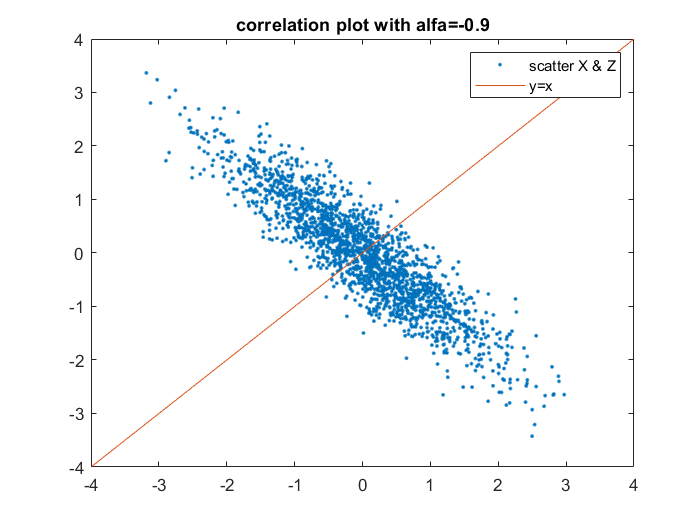

% Analysis with alfa=-0.9
Alfa3=-0.9;
Z3=Alfa3*X+sqrt(1-Alfa3^2)*Y;            
figure(14)
x=-4:0.01:4;
y=-4:0.01:4;
plot(X,Z3,".",x,y)
title('correlation plot with alfa=-0.9')
legend('scatter X & Z','y=x')

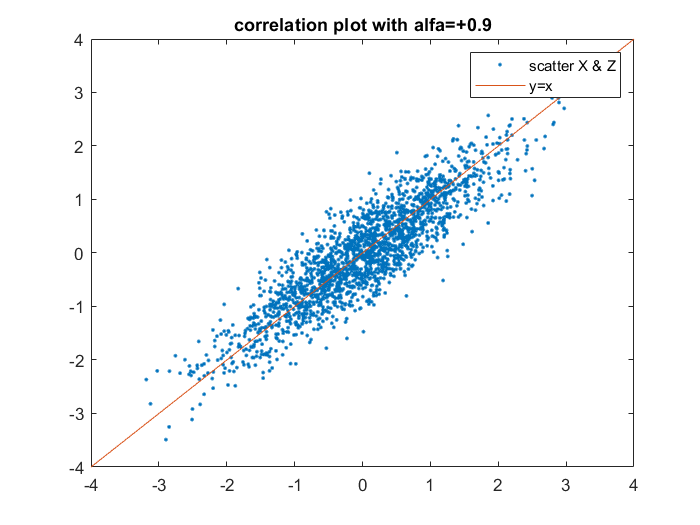

% Analysis with alfa=+0.9
Alfa4=+0.9;
Z4=Alfa4*X+sqrt(1-Alfa4^2)*Y;            
figure(15)
x=-4:0.01:4;
y=-4:0.01:4;
plot(X,Z4,".",x,y)
title('correlation plot with alfa=+0.9')
legend('scatter X & Z','y=x')

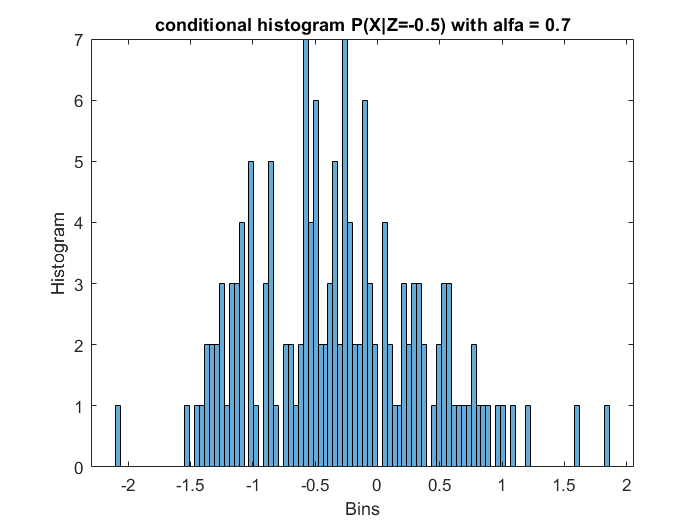



%part2_2

% Alfa= 0.7
Alfa=0.7;
Z=Alfa*X+sqrt(1-Alfa^2)*Y;
count=0;
index=0;
for i=1:1:2000
if(-0.6<Z(i) && Z(i)<-0.4)
index=index+1;
conditional_vectorAA(index)=X(i);     
end
if(0.4<Z(i) && Z(i)<0.6)
count=count+1;
conditional_vectorBB(count)=X(i);   
end
end
figure(16)
histogram(conditional_vectorAA,100)
title('conditional histogram P(X|Z=-0.5) with alfa = 0.7');
xlabel('Bins');
ylabel('Histogram');

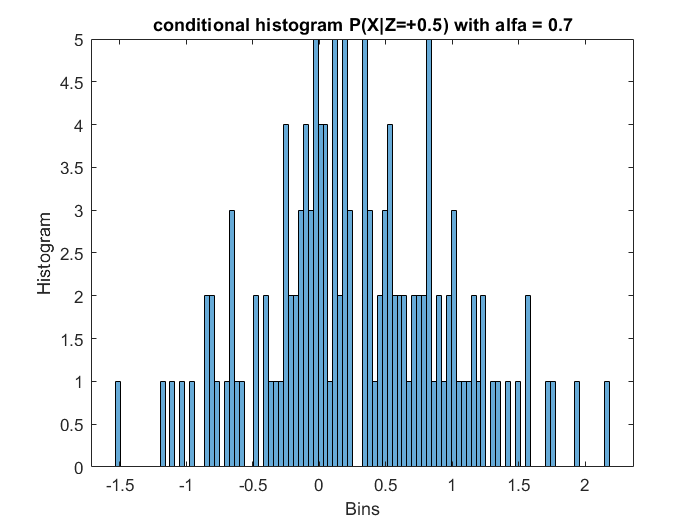


figure(17)
histogram(conditional_vectorBB,100)
title('conditional histogram P(X|Z=+0.5) with alfa = 0.7');
xlabel('Bins');
ylabel('Histogram');

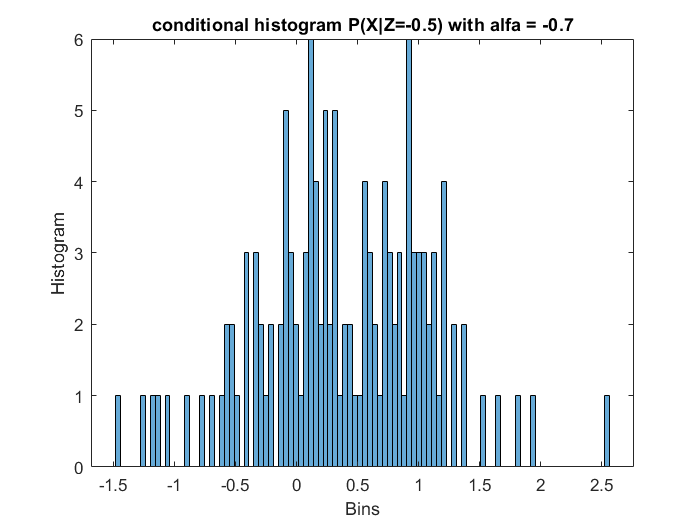



% Alfa= -0.7

Alfa=-0.7;
Z=Alfa*X+sqrt(1-Alfa^2)*Y;
count=0;
index=0;
for i=1:1:2000
if(-0.6<Z(i) && Z(i)<-0.4)
index=index+1;
conditional_vectorAAA(index)=X(i);     
end
if(0.4<Z(i) && Z(i)<0.6)
count=count+1;
conditional_vectorBBB(count)=X(i);   
end
end
figure(18)
histogram(conditional_vectorAAA,100)
title('conditional histogram P(X|Z=-0.5) with alfa = -0.7');
xlabel('Bins');
ylabel('Histogram');

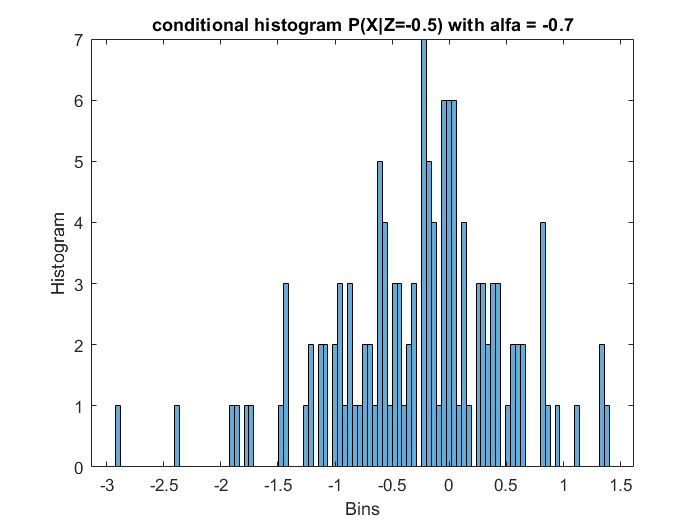

figure(19)
histogram(conditional_vectorBBB,100)
title('conditional histogram P(X|Z=-0.5) with alfa = -0.7');
xlabel('Bins');
ylabel('Histogram');




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   PART 3



%part3_1


M=zeros(256,256);

for i=1:1:256
M(i,:)=random('norm',0,sqrt(1),1,256);
muie(i)=mean(M(i,:));
time_mean(i)=mean(M(:,i));
end
mean(time_mean)

ans = -0.0023

mean(muie)

ans = -0.0028

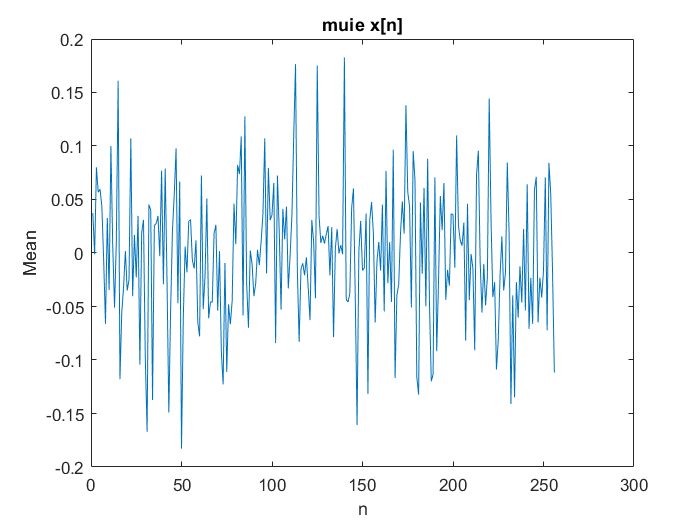

figure(22)
plot(muie)
title('muie x[n]');
xlabel('n');
ylabel('Mean');

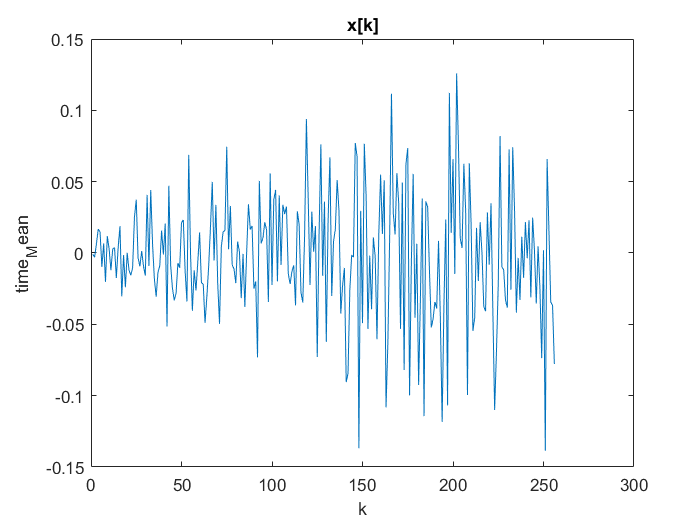


figure(23)
plot(time_mean)
title('x[k]');
xlabel('k');
ylabel('time_Mean');

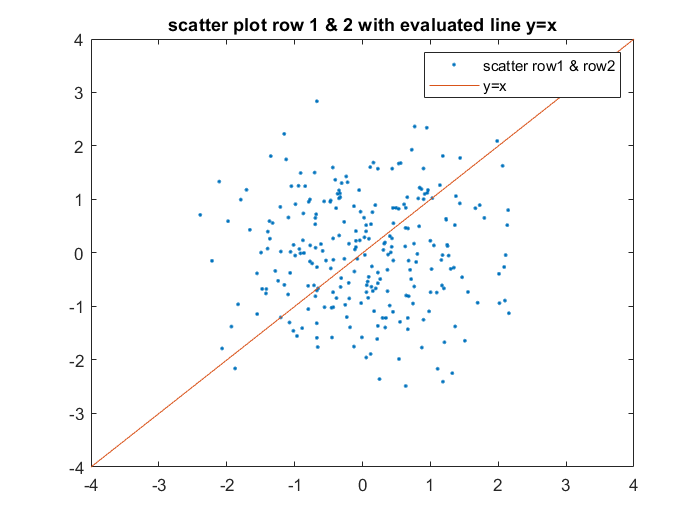


%part3_2

figure(24)
x=-4:0.01:4;
y=-4:0.01:4;
plot(M(1,:),M(2,:),".",x,y)
title('scatter plot row 1 & 2 with evaluated line y=x');
legend('scatter row1 & row2','y=x')


p=corrcoef(M(1,:),M(2,:));
hambastegii=p(2);

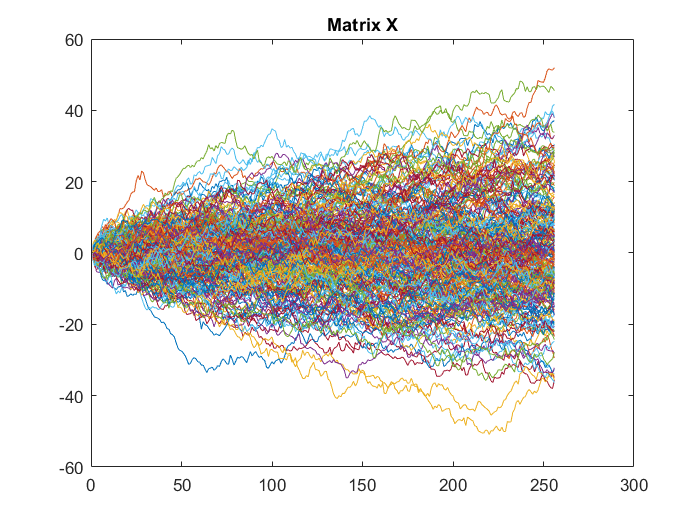



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   PART 4



% noticed that part4_1 & part4_2 & part4_3 mentioned in report
% and basically related about teoricall topics :)

%part4_4

w=randn(256,256);
matrix_X=filter(1,[1,-1],w);
figure(25)
plot(matrix_X)
title('Matrix X')

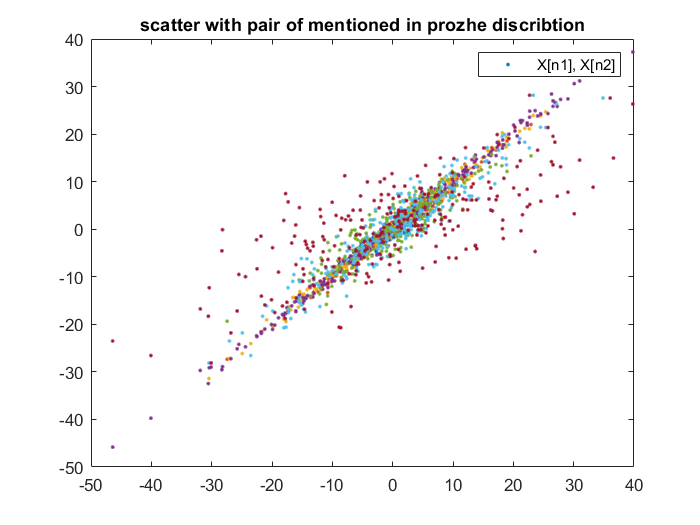


figure(26)
plot(matrix_X(10,:),matrix_X(9,:),'.',matrix_X(50,:),matrix_X(49,:),'.',matrix_X(100,:),matrix_X(99,:),'.',matrix_X(200,:),matrix_X(199,:),'.',matrix_X(50,:),matrix_X(40,:),'.',matrix_X(100,:),matrix_X(90,:),'.',matrix_X(200,:),matrix_X(90,:),'.');
title('scatter with pair of mentioned in prozhe discribtion')
legend('X[n1], X[n2]');




%part4_5

for n=2:1:256
cross_correlation(n-1)=mean(matrix_X(n,:).*matrix_X(n-1,:))
end

cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483   30.3466   31.5204   32.9397   33.8586   34.3883   35.6228   37.5164   38.3485   39.0314   40.2655   41.6156   42.4692   43.5828   45.0783   46.2617   46.9737   48.3015   50.1047   51.0754   52.0869


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483


cross_correlation =     1.0791    2.2010    3.1505    3.9338    4.8505    6.1180    7.1334    7.8551    8.6182    9.7781   11.1371   11.7483   12.2566   13.3482   14.2555   14.9572   15.7868   16.5614   17.3849   17.6528   18.4358   19.8649   20.8995   22.1383   23.7004   25.0785   25.6441   27.0108   28.5208   29.4483



n_domin=1:1:255

n_domin =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


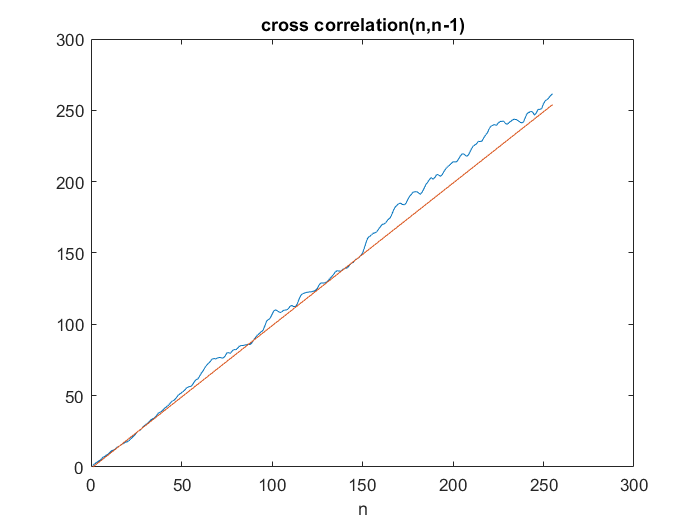

figure(27)
plot(n_domin,cross_correlation,n_domin,n_domin-1)
title('cross correlation(n,n-1)')
xlabel('n')